a = arduino()

a =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'I2C', 'SPI', 'Servo'}
Show all properties


Enter the amount of time you want to sense for:

T = 100; % seconds
dt = 0.1; 

N = T/dt;


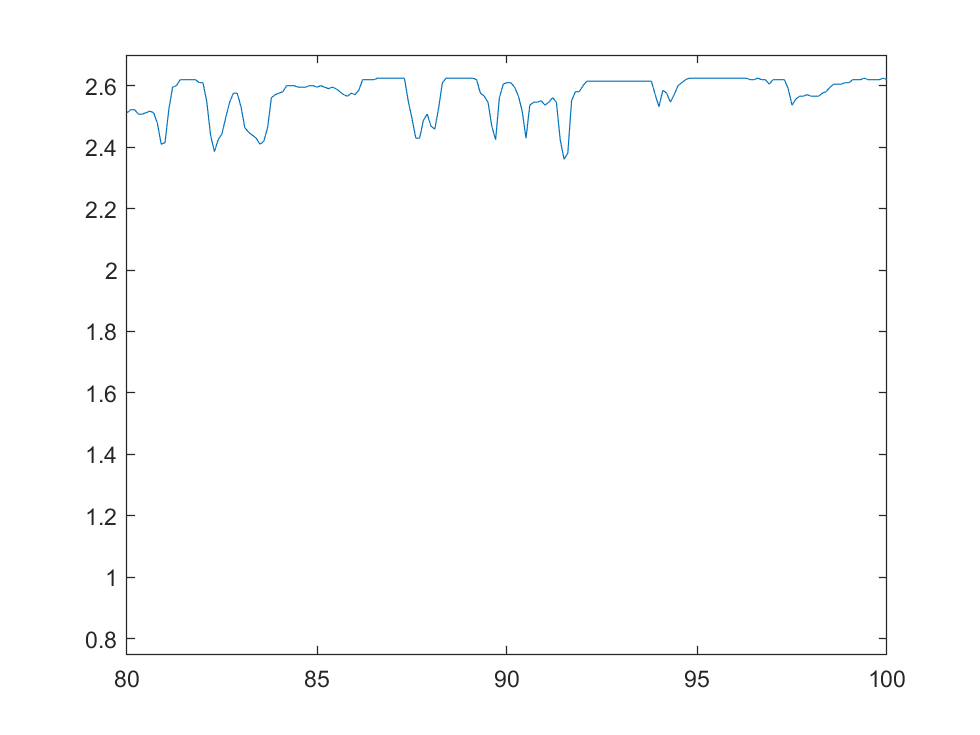

signal = zeros(N, 1);
time = dt*(1:N).';
figure;
for jj = 1:N
    signal(jj) = a.readVoltage('A0');
    
    if jj<=200
        plot(time(1:jj), signal(1:jj));
    else
        plot(time(jj-200:jj), signal(jj-200:jj));
    end
    ylim([0.75 2.7])
    drawnow
    pause(dt);
end